## Using parareal algorithm to train a Fully Connected Neural Network

Reproduce the classification task of the paper

clear all; close all; clc;
addpath("parareal_systems\")

Dataset (from the paper)

x1 = [0.1,0.3,0.1,0.6,0.4];
y1 = [0.1,0.4,0.5,0.9,0.2];

x2 = [0.6,0.5,0.9,0.4,0.7];
y2 = [0.3,0.6,0.2,0.4,0.6];

x = [x1, x2; y1, y2];
y = [ones(1,5) zeros(1,5); zeros(1,5) ones(1,5)];

Nefine network hyperparameters

sigma = @(t) 1./(1+exp(-t));
sigmaprime = @(t) sigma(t).*(1-sigma(t));
shape = [2, 3, 3, 2];
niter = 1e4;
eta = 0.05;

### Train network with parareal

disp('begin')

begin


tic
[W_, b_] = TrainNetworkParareal( ...
        x, y, niter, eta, sigma, sigmaprime, shape);

T=500
iteration 1/20
iteration 2/20
iteration 3/20
iteration 4/20
iteration 5/20
iteration 6/20
iteration 7/20
iteration 8/20
iteration 9/20
iteration 10/20
iteration 11/20
iteration 12/20
iteration 13/20
iteration 14/20
iteration 15/20
iteration 16/20
iteration 17/20
iteration 18/20
iteration 19/20
iteration 20/20


toc

Elapsed time is 67.362756 seconds.


disp('end')

end


### Compare results with previous training

load reference.mat

normsw = [];
normsb = [];
for l = 1:numel(shape)-1
    normsw = [normsw, norm(W{l}-W_{l},2)];
    normsb = [normsb, norm(b{l}-b_{l},2)];
end

Display predictions with previous training 

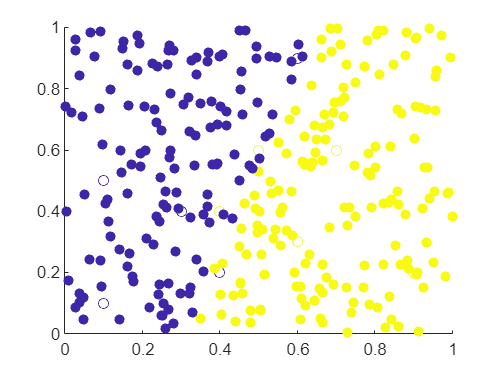

n = 300;
testDatax = rand(n, 2);
testDatay = PredictClasses(W, b, sigma, testDatax');

x = x';
y = int32([zeros(5, 1); ones(5, 1)]');
figure
scatter(x(:,1), x(:,2), [], y, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');

Display predictions with new training

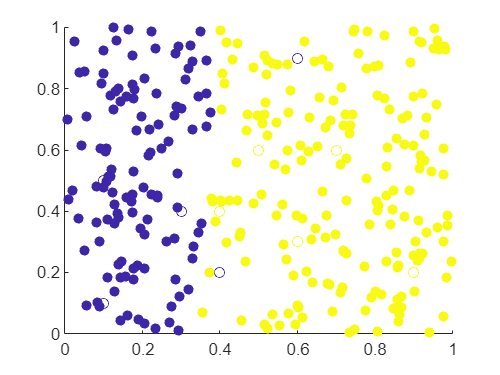

n = 300;
testDatax = rand(n, 2);
testDatay = PredictClasses(W_, b_, sigma, testDatax');

y = int32([zeros(5, 1); ones(5, 1)]');
figure
scatter(x(:,1), x(:,2), [], y, 'o');
hold on;
scatter(testDatax(:,1), testDatax(:,2), [], testDatay, 'filled');